De Veld, D. C. G., Witjes, M. J. H., Sterenborg, H. J. C. M., & Roodenburg, J. L. N. (2005). The status of in vivo autofluorescence spectroscopy and imaging for oral oncology. *Oral oncology*, *41*(2), 117-131.

This is a review paper that makes many good points.  

The paper also includes a Figure that plots the MEAN spectra for different tumor classifications (excluding tumors on the dorsal tongue and vermilion border of the lip)

This script shows that we can predict the mean spectra for the different tissue types using our model, however, 

TODO: smooth the data - or sample more finely

ieInit;
wave = 500:600;
normWave = 520;
% fise_plotDefaults;
 

## Read the saved model fluorophores

These have no blood.  The blood will be read in during the fitting process with oeSolveBlood.

fname = fullfile(oeTongueLipRootPath,'data','savedFluorophores');
[savedFluorophores,~,comment] = ieReadSpectra(fname,wave);
%{
plotRadiance(wave,savedFluorophores);
legend(comment.names);
%}

## Read the external data

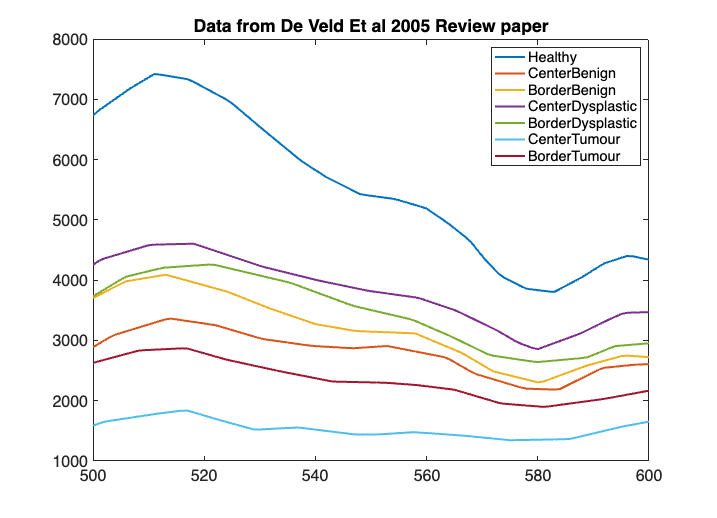


BorderBenign = ieReadSpectra('BorderBenign.mat',wave);
BorderDysplastic = ieReadSpectra('BorderDysplastic.mat',wave);
BorderTumour = ieReadSpectra('BorderTumour.mat',wave);
CenterBenign = ieReadSpectra('CenterBenign.mat',wave);
CenterDysplastic = ieReadSpectra('CenterDysplastic.mat',wave);
CenterTumour = ieReadSpectra('CenterTumour.mat',wave);
Healthy = ieReadSpectra('Healthy.mat',wave);

ieFigure; 
plot(wave,Healthy); hold on;
plot(wave,CenterBenign);
plot(wave,BorderBenign);
plot(wave,CenterDysplastic);
plot(wave,BorderDysplastic);
plot(wave,CenterTumour);
plot(wave,BorderTumour); 
title('Data from De Veld Et al 2005 Review paper');
legend('Healthy','CenterBenign','BorderBenign','CenterDysplastic','BorderDysplastic','CenterTumour','BorderTumour'); 
lines = findall(gca, 'Type', 'Line');
set(lines,'LineWidth', 2);
set(gca,'fontsize',16); set(gca, 'FontName', 'Helvetica');

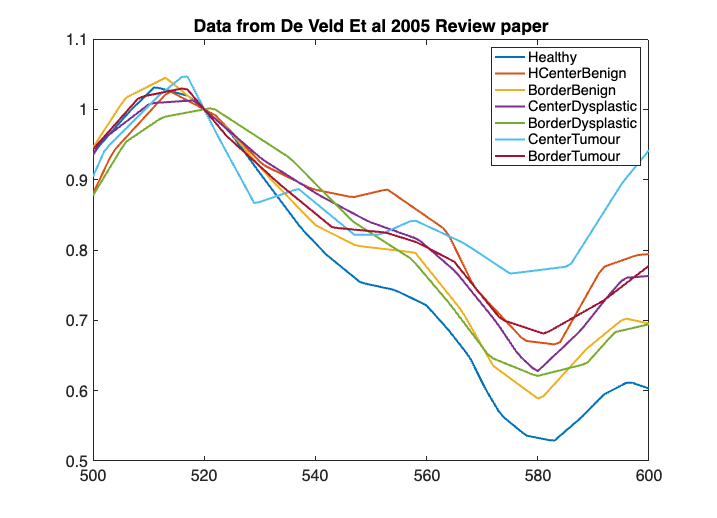


BorderBenign = BorderBenign/BorderBenign(wave == 520);
BorderDysplastic= BorderDysplastic/BorderDysplastic(wave == 520);
BorderTumour = BorderTumour/BorderTumour(wave == 520);
CenterBenign = CenterBenign/CenterBenign(wave == 520);
BorderBenign = BorderBenign/BorderBenign(wave == 520);
CenterDysplastic = CenterDysplastic/CenterDysplastic(wave == 520);
CenterTumour = CenterTumour/CenterTumour(wave == 520);
Healthy = Healthy/Healthy(wave == 520);

ieFigure; 
plot(wave,Healthy); hold on;
plot(wave,CenterBenign);
plot(wave,BorderBenign);
plot(wave,CenterDysplastic);
plot(wave,BorderDysplastic);
plot(wave,CenterTumour);
plot(wave,BorderTumour); 
title('Data from De Veld Et al 2005 Review paper');
legend('Healthy','HCenterBenign','BorderBenign','CenterDysplastic','BorderDysplastic','CenterTumour','BorderTumour'); 
lines = findall(gca, 'Type', 'Line');
set(lines, 'LineWidth', 2);
set(gca,'fontsize',16); set(gca, 'FontName', 'Helvetica');

## Fit the model to healthy tissue

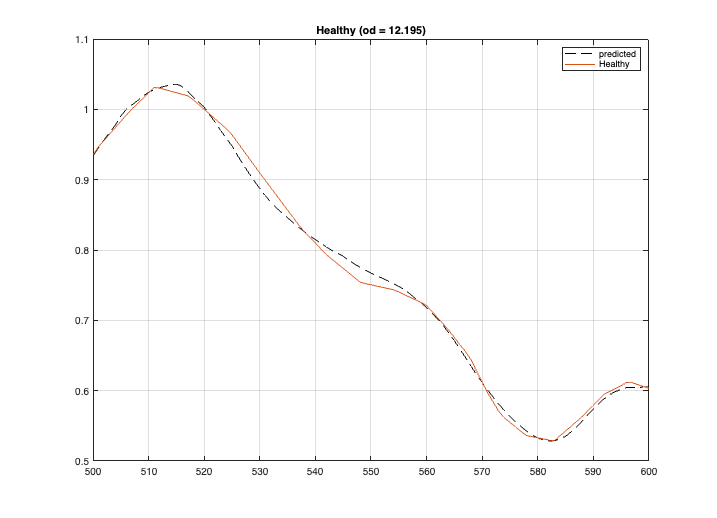

[odH,weightsH,finalFluorophoresH] = oeSolveBlood(wave,Healthy,savedFluorophores);
predictedH = finalFluorophoresH*weightsH(:);
ieFigure;
plot(wave,predictedH,'k--',wave,Healthy);
grid on;
title(sprintf('Healthy (od = %.3f)',odH));
legend("predicted","Healthy");


labels = {'Blood', 'Collagen-blood', 'FAD', 'Porphyrin', 'Chlorophyll-a', 'Keratin'};
values = [odH; weightsH(:)]; 
maxLabelWidth = max(cellfun(@length, labels));
for i = 1:length(labels)
    if i==1, fprintf('Tissue: Center Tumour\n'); end
    fprintf('%*s  %.2f\n', maxLabelWidth, labels{i}, values(i));
end

Tissue: Center Tumour


         Blood  12.19
Collagen-blood  8.44
           FAD  0.56
     Porphyrin  0.00
 Chlorophyll-a  0.00
       Keratin  0.35


## Fit the model to the Center Tumor

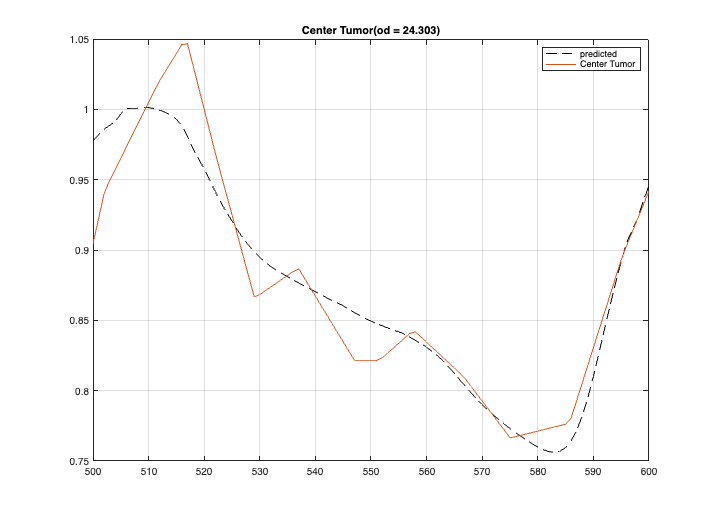

[odCT,weightsCT,finalFluorophoresCT] = oeSolveBlood(wave,CenterTumour,savedFluorophores);
predictedCT = finalFluorophoresCT*weightsCT(:);
ieFigure;
plot(wave,predictedCT,'k--',wave,CenterTumour);
grid on;
title(sprintf('Center Tumor(od = %.3f)',odCT));
legend("predicted","Center Tumor");


labels = {'Blood', 'Collagen-blood', 'FAD', 'Porphyrin', 'Chlorophyll-a', 'Keratin'};
values = [odCT; weightsCT(:)]; 
maxLabelWidth = max(cellfun(@length, labels));
for i = 1:length(labels)
    if i==1, fprintf('Tissue: Center Tumour\n'); end
    fprintf('%*s  %.2f\n', maxLabelWidth, labels{i}, values(i));
end

Tissue: Center Tumour


         Blood  24.30
Collagen-blood  11.86
           FAD  0.18
     Porphyrin  0.00
 Chlorophyll-a  0.00
       Keratin  0.92


## Fit the model to the Border Tumor

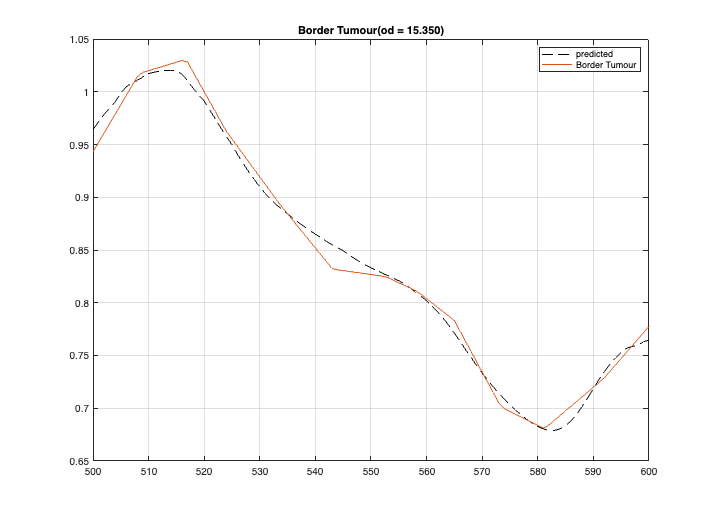

[odBT,weightsBT,finalFluorophoresBT] = oeSolveBlood(wave,BorderTumour,savedFluorophores);
predictedBT = finalFluorophoresBT*weightsBT(:);
ieFigure;
plot(wave,predictedBT,'k--',wave,BorderTumour);
grid on;
title(sprintf('Border Tumour(od = %.3f)',odBT));
legend("predicted","Border Tumour");


labels = {'Blood', 'Collagen-blood', 'FAD', 'Porphyrin', 'Chlorophyll-a', 'Keratin'};
values = [odBT; weightsBT(:)]; 
maxLabelWidth = max(cellfun(@length, labels));
for i = 1:length(labels)
    if i==1, fprintf('Tissue: Border Tumour\n'); end
    fprintf('%*s  %.2f\n', maxLabelWidth, labels{i}, values(i));
end

Tissue: Border Tumour


         Blood  15.35
Collagen-blood  7.25
           FAD  0.34
     Porphyrin  0.00
 Chlorophyll-a  0.00
       Keratin  0.71


## Fit the model to the Center Dysplastic

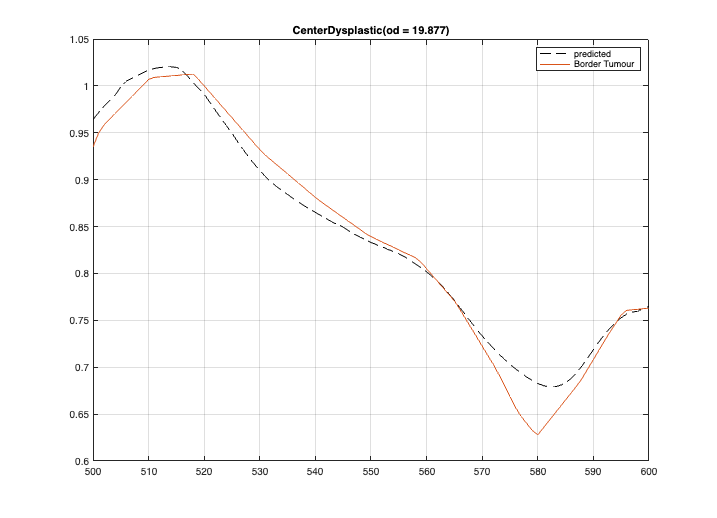

[odCD,weightsCD,finalFluorophoresCD] = oeSolveBlood(wave,CenterDysplastic,savedFluorophores);
predictedCD = finalFluorophoresCD*weightsCD(:);
ieFigure;
plot(wave,predictedBT,'k--',wave,CenterDysplastic);
grid on;
title(sprintf('CenterDysplastic(od = %.3f)',odCD));
legend("predicted","Border Tumour");

labels = {'Blood', 'Collagen-blood', 'FAD', 'Porphyrin', 'Chlorophyll-a', 'Keratin'};
values = [odCD; weightsCD(:)]; 
maxLabelWidth = max(cellfun(@length, labels));
for i = 1:length(labels)
    if i==1, fprintf('Tissue: CenterDysplastic\n'); end
    fprintf('%*s  %.2f\n', maxLabelWidth, labels{i}, values(i));
end

Tissue: CenterDysplastic


         Blood  19.88
Collagen-blood  9.69
           FAD  0.43
     Porphyrin  0.00
 Chlorophyll-a  0.00
       Keratin  0.63


## Fit the model to the Border Dysplastic

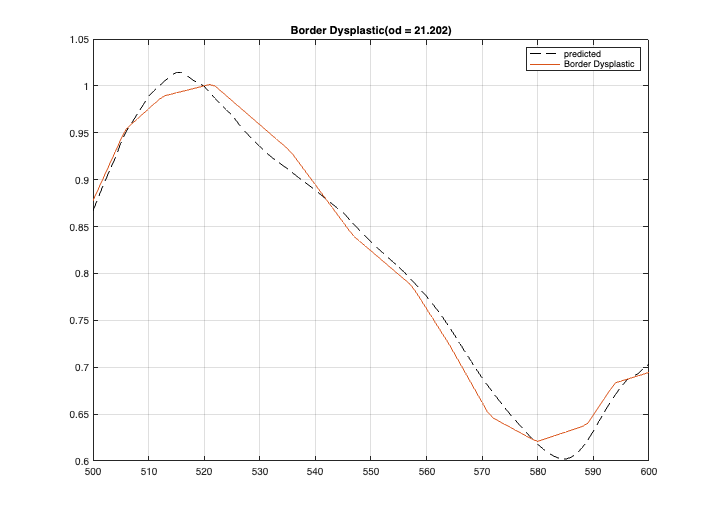

[odBD,weightsBD,finalFluorophoresBD] = oeSolveBlood(wave,BorderDysplastic,savedFluorophores);
predictedBD = finalFluorophoresBD*weightsBD(:);
ieFigure;
plot(wave,predictedBD,'k--',wave,BorderDysplastic);
grid on;
title(sprintf('Border Dysplastic(od = %.3f)',odBD));
legend("predicted","Border Dysplastic");

labels = {'Blood', 'Collagen-blood', 'FAD', 'Porphyrin', 'Chlorophyll-a', 'Keratin'};
values = [odBD; weightsBD(:)]; 
maxLabelWidth = max(cellfun(@length, labels));
for i = 1:length(labels)
    if i==1, fprintf('Tissue: Border Dysplastic\n'); end
    fprintf('%*s  %.2f\n', maxLabelWidth, labels{i}, values(i));
end

Tissue: Border Dysplastic


         Blood  21.20
Collagen-blood  9.40
           FAD  0.55
     Porphyrin  0.00
 Chlorophyll-a  0.00
       Keratin  0.50


## Fit the model to the Center Benign

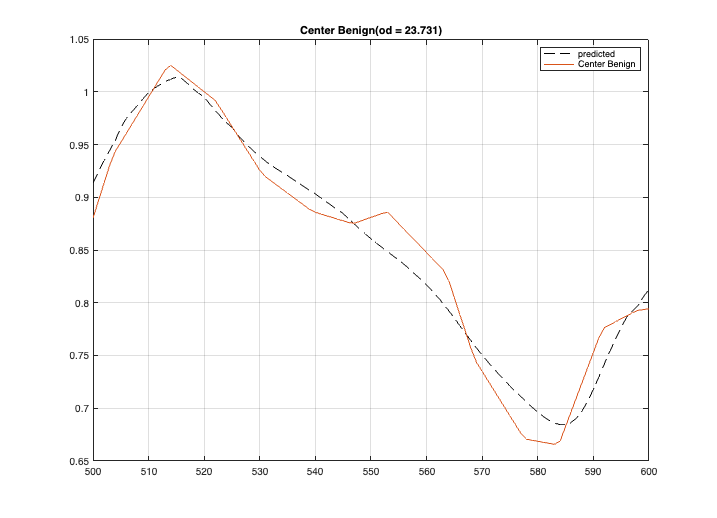

[odCB,weightsCB,finalFluorophoresCB] = oeSolveBlood(wave,CenterBenign,savedFluorophores);
predictedCB = finalFluorophoresCB*weightsCB(:);
ieFigure;
plot(wave,predictedCB,'k--',wave,CenterBenign);
grid on;
title(sprintf('Center Benign(od = %.3f)',odCB));
legend("predicted","Center Benign");

labels = {'Blood', 'Collagen-blood', 'FAD', 'Porphyrin', 'Chlorophyll-a', 'Keratin'};
values = [odCB; weightsCB(:)]; 
maxLabelWidth = max(cellfun(@length, labels));
for i = 1:length(labels)
    if i==1, fprintf('Tissue: Center Benign\n'); end
    fprintf('%*s  %.2f\n', maxLabelWidth, labels{i}, values(i));
end

Tissue: Center Benign


         Blood  23.73
Collagen-blood  10.07
           FAD  0.40
     Porphyrin  0.00
 Chlorophyll-a  0.00
       Keratin  0.70


## Fit the model to the Border Benign

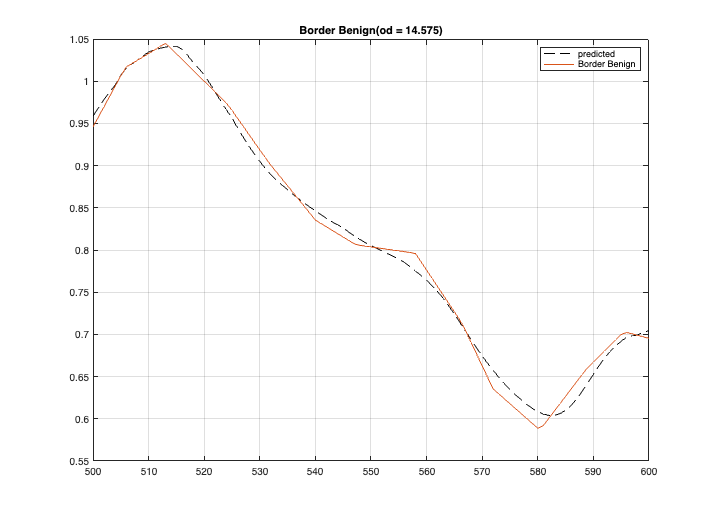

[odBB,weightsBB,finalFluorophoresBB] = oeSolveBlood(wave,BorderBenign,savedFluorophores);
predictedBB = finalFluorophoresBB*weightsBB(:);
ieFigure;
plot(wave,predictedBB,'k--',wave,BorderBenign);
grid on;
title(sprintf('Border Benign(od = %.3f)',odBB));
legend("predicted","Border Benign");

labels = {'Blood', 'Collagen-blood', 'FAD', 'Porphyrin', 'Chlorophyll-a', 'Keratin'};
values = [odBB; weightsBB(:)]; 
maxLabelWidth = max(cellfun(@length, labels));
for i = 1:length(labels)
    if i==1, fprintf('Tissue: Border Benign\n'); end
    fprintf('%*s  %.2f\n', maxLabelWidth, labels{i}, values(i));
end

Tissue: Border Benign


         Blood  14.58
Collagen-blood  8.80
           FAD  0.47
     Porphyrin  0.00
 Chlorophyll-a  0.00
       Keratin  0.52
